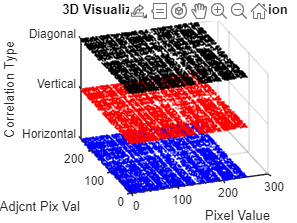

% Read and convert image to grayscale
gray_img = C2;  % Replace with your image file
[m, n] = size(gray_img);

% Get adjacent pixel values for different directions
horizontal_x = double(gray_img(:, 1:n-1));
horizontal_y = double(gray_img(:, 2:n));

vertical_x = double(gray_img(1:m-1, :));
vertical_y = double(gray_img(2:m, :));

diagonal_x = double(gray_img(1:m-1, 1:n-1));
diagonal_y = double(gray_img(2:m, 2:n));

% Flatten the matrices into vectors
h_x = horizontal_x(:); h_y = horizontal_y(:);
v_x = vertical_x(:); v_y = vertical_y(:);
d_x = diagonal_x(:); d_y = diagonal_y(:);

% Define Z-axis offsets for visualization
h_z = ones(size(h_x)) * 0;  % Horizontal at z = 0
v_z = ones(size(v_x)) * 1;  % Vertical at z = 1
d_z = ones(size(d_x)) * 2;  % Diagonal at z = 2

% Create 3D scatter plot
figure;
scatter3(h_x, h_y, h_z, 1, 'b', 'filled'); hold on;
scatter3(v_x, v_y, v_z, 1, 'r', 'filled');
scatter3(d_x, d_y, d_z, 1, 'k', 'filled');

% Labels and appearance
xlabel('Pixel Value');
ylabel('Adjcnt Pix Val');
zlabel('Correlation Type');
zticks([0 1 2]); % Assign labels to Z-axis
zticklabels({'Horizontal', 'Vertical', 'Diagonal'});
grid on;
title('3D Visualization of Pixel Correlation');

% Adjust view angle
view(-20, 30);